% AAE 364L MATLAB CODE
% TOMOKI KOIKE
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Load result data

pp_xc = load("koike_lab3_results\koike_position_PP_lab3.mat");
pp_theta = load("koike_lab3_results\koike_theta_PP_lab3.mat");
lqr_xc = load("koike_lab3_results\koike_position_LQR_lab3.mat");
lqr_theta = load("koike_lab3_results\koike_theta_LQR_lab3.mat");

% PP

t = pp_xc.position_part2.time;
xc = pp_xc.position_part2.signals.values;
theta = pp_theta.theta_part2.signals.values;

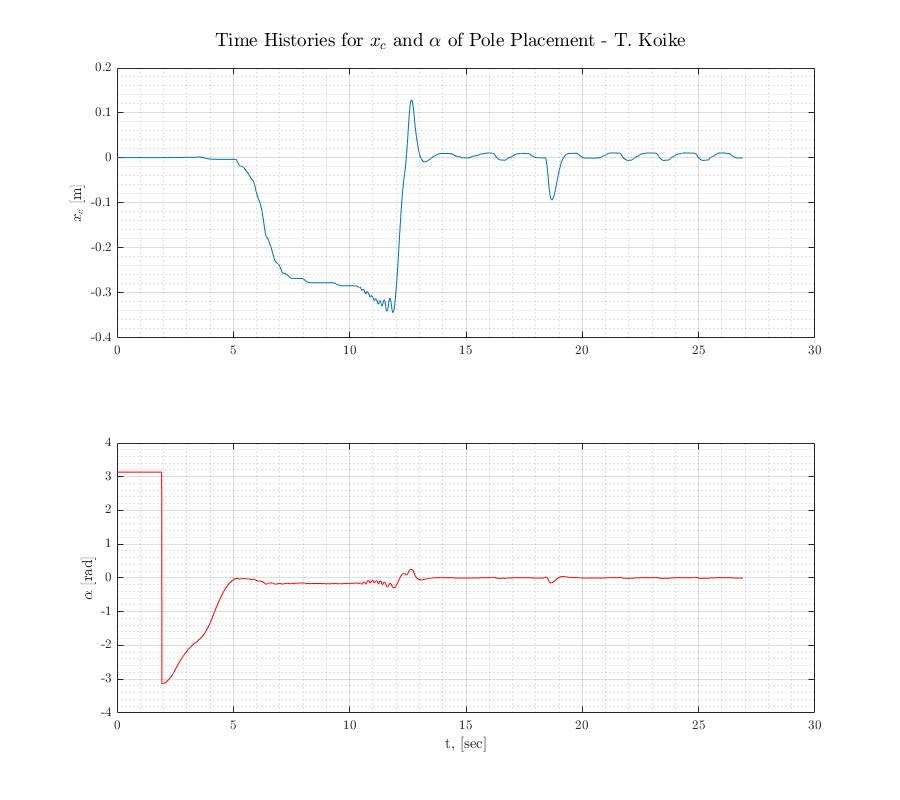

% Plotting 
fig = figure('Renderer',"painters", 'Position', [10 10 900 800]);
subplot(2,1,1)
plot(t,xc)
grid on; grid minor; box on;
ylabel('$x_c$ [m]')
subplot(2,1,2)
plot(t,theta, '-r')
grid on; grid minor; box on;
ylabel('$\alpha$ [rad]')
xlabel('t, [sec]')
sgtitle('Time Histories for $x_c$ and $\alpha$ of Pole Placement - T. Koike')
saveas(fig, 'pp_history.png')

% PP

t = lqr_xc.position_part2.time;
xc = lqr_xc.position_part2.signals.values;
theta = lqr_theta.theta_part2.signals.values;

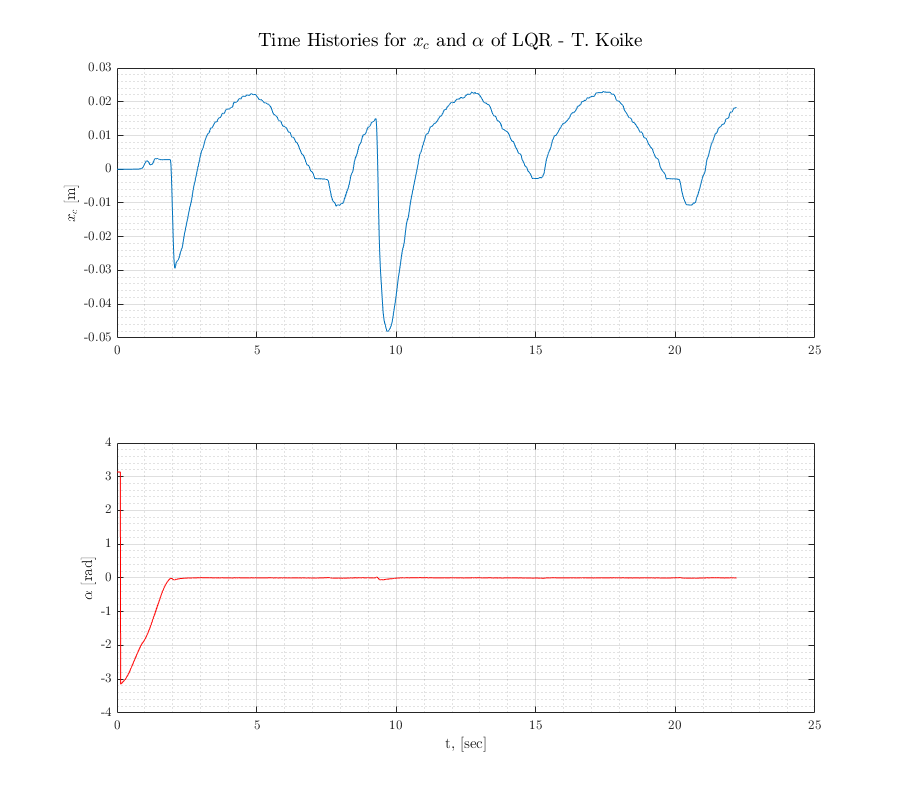

% Plotting 
fig = figure('Renderer',"painters", 'Position', [10 10 900 800]);
subplot(2,1,1)
plot(t,xc)
grid on; grid minor; box on;
ylabel('$x_c$ [m]')
subplot(2,1,2)
plot(t,theta, '-r')
grid on; grid minor; box on;
ylabel('$\alpha$ [rad]')
xlabel('t, [sec]')
sgtitle('Time Histories for $x_c$ and $\alpha$ of LQR - T. Koike')
saveas(fig, 'lqr_history.png')